# COVID-19 SEIR Modeling and Forecasting

**Objective**: Predict daily confirmed COVID-19 cases and fatalities in the US

**Model**: SEIR with fatality component

**States**: Susceptible ($S$), Exposed ($E$), Infected ($I$), Recovered ($R$), Deceased ($D$)

**Parameters**: Infection Rate ($\beta$), Latency Period ($1/\alpha$), Recovery Rate ($\gamma$), Fatality Rate of Disease ($f$)

**Model Equations**:


$$\frac{dS}{dt} =- \beta \frac{S I}{N}
\]$$



$$\frac{dE}{dt} = \beta \frac{S I}{N} - \alpha E$$



$$\frac{dI}{dt} = \alpha E -(\gamma + f) I$$



$$\frac{dR}{dt} = \gamma I$$



$$\frac{dD}{dt} = f I$$


**Notes**:

- Total population (excluding deceased) is $N = S+E+I+R$.

- The natural birth and death rates are assumed to be equal and negligible over the simulation period.  

- Disease fatalities are tracked separately in $D$. 

- Due to changes in population behavior and mitigation measures during the COVID-19 outbreak in the United States, the infection rate is modeled using two regimes: a pre-change transmission rate ($\beta_1$) and and a post-change transmission rate ($\beta_2$). The model assumes a linear transition between these rates over a period ending on day $t_{change}$ after which the transmission rate remains constant at $\beta_2$.

**Data Source**: "COVID-19 Data Repository by the Center for Systems Science and Engineering (CSSE) at Johns Hopkins University" [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Project Introduction

This COVID-19 data is from the COVID19 Global Forecasting competition on Kaggle, filtered and aggregated for the US. 

In this project, we explore **frequentist** and **Bayesian techniques** that enable estimation of model parameters and variance. By combining these estimates, one can infer the likely values of true, but unknown, parameters and forecast future observations.

These techniques were explored in detail in the *Uncertainty Quantification for Physical and Biological Models* course at NC State University, taught by Professor Ralph Smith.

Day 1 is identified as the first day with over 500 confirmed cases: March 13, 2020.

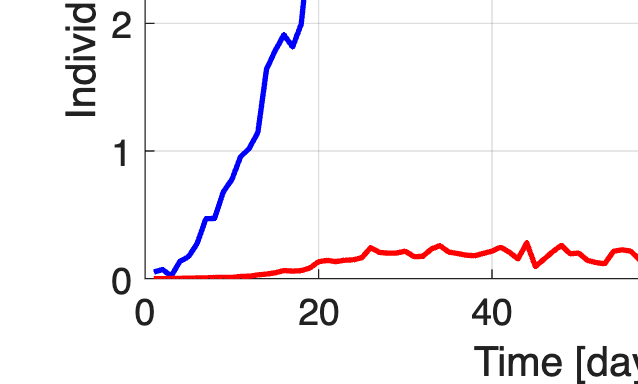

clear; clc; clf;

% Load preprocessed data
data_us_clean = readtable('covid19_us_cleaned.csv');
data_us       = readtable('covid19_us.csv');

% Extract daily data
t_daily = data_us_clean.Day;
N_daily = data_us_clean.Population;
I_daily = data_us_clean.ConfirmedCases;
F_daily = data_us_clean.Fatalities;
D_daily = cumsum(F_daily);

% Plot daily US confirmed cases and fatalities
figure;
plot(t_daily, I_daily, 'b-x', 'LineWidth', 2, 'MarkerSize', 6); hold on;
plot(t_daily, F_daily, 'r-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Time [days]'); ylabel('Individuals');
legend('Confirmed Cases','Fatalities'); grid on;
set(gca,'FontSize',14); title('Daily US COVID-19 Data');

**Observation: **The daily data displays noticeable cyclical behavior, likely due to differences in reporting practices across days of the week. This would cause the model residuals to not be independent and identically distributed (iid).

**Response: **Aggregating the data weekly smooths these effects while preserving overall trends.

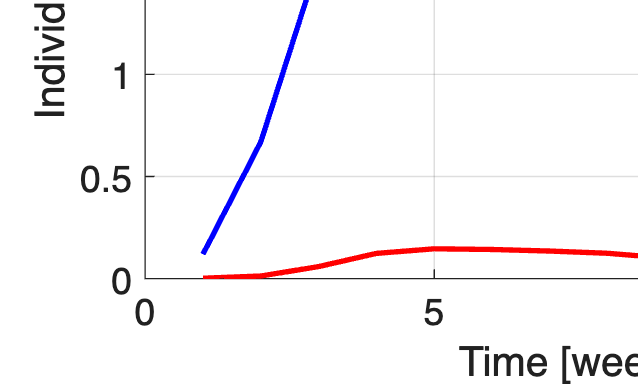

% Aggregate to weekly data
t_weekly = unique(data_us_clean.Week);
N_weekly = accumarray(data_us_clean.Week, data_us_clean.Population, [], @max);
I_weekly = accumarray(data_us_clean.Week, data_us_clean.ConfirmedCases);
F_weekly = accumarray(data_us_clean.Week, data_us_clean.Fatalities);
D_weekly = cumsum(F_weekly);

% Plot weekly US confirmed cases and fatalities
figure;
plot(t_weekly, I_weekly, 'b-x', 'LineWidth', 2, 'MarkerSize', 6); hold on;
plot(t_weekly, F_weekly, 'r-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Time [weeks]'); ylabel('Individuals');
legend('Confirmed Cases','Fatalities'); grid on;
set(gca,'FontSize',14); title('Weekly US COVID-19 Data');

## Estimating Parameters and Variance

The first thing we will do is identify the parameters for this model by minimizing the sum of the squared errors (the difference between the observed data and various model fits. To do so, we can use the fmincon() function in MATLAB to optimize the function while enabling realistic constraints on the possible values of our parameters when soliving for an optimal solution.

### **Frequentist Techniques**

% Initial states
I0 = I_daily(1);
E0 = 2*I0;
D0 = D_daily(1);
S0 = N_daily(1) - I0 - E0 - D0;
R0 = 0;
Y0 = [S0; E0; I0; R0; D0];

% Initial parameters
beta1_init   = 0.6; % pre-change transmission rate
beta2_init   = 0.2; % post-change transmission rate
alpha_init   = 1/4; % 4-day incubation period
gamma_init   = 1/7; % 7-day infectious period
f_init       = mean(F_daily ./ I_daily);
tchange_init = 28;    % Day of beta change
q_init       = [beta1_init, beta2_init, alpha_init, gamma_init, f_init, tchange_init];

% Bounding the possible values of the parameters
lb = [0 0 0 0 0 1];
ub = [1 1 12 1 0.06 max(t_daily)];

% Setting up and solving for optimal parameters
options = optimset('Display','final','TolX',1e-8,'TolFun',1e-8,'MaxIter',500,'MaxFunEvals',5000);
odeopt  = odeset('RelTol',1e-7,'AbsTol',1e-9);

modelfun = @(q) seir_ss(q, t_daily, I_daily, D_daily, Y0, N_daily, odeopt);
q_ols = fmincon(modelfun, q_init, [], [], [], [], lb, ub, [], options);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% q_ols = [beta1_ols, beta2_ols, alpha_ols, gamma_ols, f_ols, tchange_ols];

fprintf('OLS Parameter Estimates:\n');

OLS Parameter Estimates:


fprintf('------------------------\n');

------------------------


fprintf('Pre-change Infection Rate (beta1): %.4f\n', q_ols(1));

Pre-change Infection Rate (beta1): 0.8816


fprintf('Post-change Infection Rate (beta2): %.4f\n', q_ols(2));

Post-change Infection Rate (beta2): 0.3314


fprintf('Latency Period (1/alpha): %.4f days\n', 1/q_ols(3));  % display as days

Latency Period (1/alpha): 1.5767 days


fprintf('Recovery Rate (gamma): %.4f per day\n', q_ols(4));

Recovery Rate (gamma): 0.2864 per day


fprintf('Fatality Rate of Disease (f): %.4f\n', q_ols(5));

Fatality Rate of Disease (f): 0.0592


fprintf('Transition for Infection Rate (tchange): %.0f\n', q_ols(6));

Transition for Infection Rate (tchange): 27


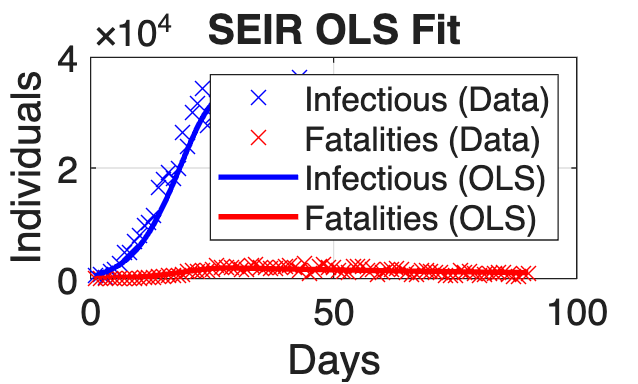

[~,Y_freq] = ode45(@(t,y) seir_rhs(t,y,q_ols,N_daily,t_daily), t_daily, Y0, odeopt);
I_freq = Y_freq(:,3);
D_freq = Y_freq(:,5);
F_freq = [D_freq(1); diff(D_freq)];

%% Plot OLS Model vs Data
figure;
plot(t_daily, I_daily,'bx','MarkerSize',8); hold on;
plot(t_daily, F_daily,'rx','MarkerSize',8);
plot(t_daily, I_freq,'b','LineWidth',2);
plot(t_daily, F_freq,'r','LineWidth',2);
xlabel('Days'); ylabel('Individuals');
legend('Infectious (Data)','Fatalities (Data)','Infectious (OLS)','Fatalities (OLS)');
grid on; set(gca,'FontSize',14); title('SEIR OLS Fit');

Again we look at the the model fit based on the data aggregated weekly.

% Aggregate model data weekly
I_freq_weekly = accumarray(data_us_clean.Week, I_freq);
week_idx = accumarray(data_us_clean.Week, (1:numel(data_us_clean.Week))', [], @max);
D_freq_weekly = Y_freq(week_idx, 5);
F_freq_weekly = [D_freq_weekly(1); diff(D_freq_weekly)];

%% Plot weekly
figure;
plot(t_weekly, I_weekly,'bx','MarkerSize',8); hold on;
plot(t_weekly, F_weekly,'rx','MarkerSize',8);
plot(t_weekly, I_freq_weekly,'b','LineWidth',2);
plot(t_weekly, F_freq_weekly,'r','LineWidth',2);
xlabel('Weeks'); ylabel('Individuals');
legend('Infectious (Data)','Fatalities (Data)','Infectious (OLS)','Fatalities (OLS)');
grid on; set(gca,'FontSize',14); title('SEIR OLS Fit');

### Bayesian Techniques

- DRAM Parameter and Variance Estimation

% Setup model for mcmcrun

odeopt = odeset('RelTol',1e-7,'AbsTol',1e-9);

clear data model options

data.tdata = t_daily;
data.ydata = I_daily;
data.D     = D_daily;
data.Y0    = Y0;
data.N     = N_daily;
data.odeopt= odeopt;

params = {
    {'beta_1',q_ols(1),0,1}
    {'beta_2',q_ols(2),0,1}
    {'alpha',  q_ols(3),0,12}
    {'gamma',  q_ols(4),0,1}
    {'f',      q_ols(5),0,0.075}
    {'tchange',q_ols(6),1,max(t_daily)}
};
model.ssfun = @(q, d) seir_ss(q, data.tdata, data.ydata, data.D, data.Y0, data.N, data.odeopt);
options.nsimu = 30000;
options.adaptint = 100;
options.updatesigma = 1;
options.drscale = 5;

[results,chain,s2chain] = mcmcrun(model,data,params,options);

Sampling these parameters:
name   start [min,max] N(mu,s^2)
beta_1: 0.881607 [0,1] N(0,Inf)
beta_2: 0.331438 [0,1] N(0,Inf)
alpha: 0.634238 [0,12] N(0,Inf)
gamma: 0.286393 [0,1] N(0,Inf)
f: 0.0591571 [0,0.075] N(0,Inf)
tchange: 27.1307 [1,90] N(0,Inf)


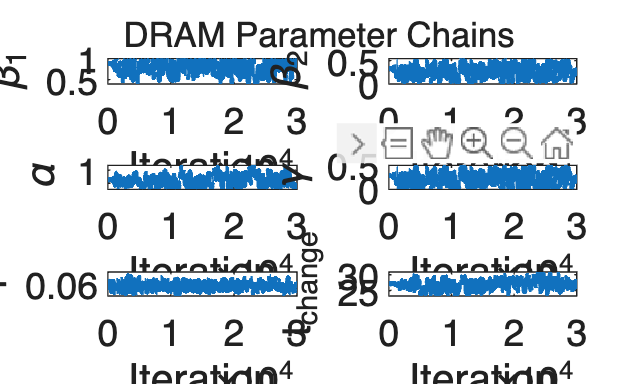


%% DRAM Chains and Marginal Densities
param_names = {'\beta_1','\beta_2','\alpha','\gamma','f','t_{change}'};
chains = num2cell(chain,1);

% Chain plots
figure;
for i=1:6
    subplot(3,2,i); plot(chains{i},'LineWidth',2); xlabel('Iteration'); ylabel(param_names{i});
    set(gca,'FontSize',14); box on;
end
sgtitle('DRAM Parameter Chains');

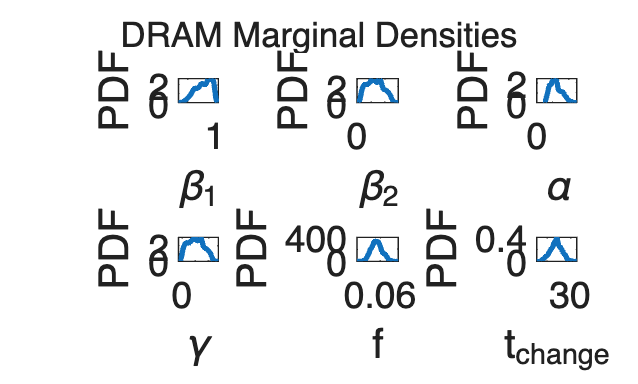


% Marginal densities
figure;
for i=1:6
    subplot(2,3,i);
    [f_est,x_mesh] = ksdensity(chains{i});
    plot(x_mesh,f_est,'LineWidth',2);
    xlabel(param_names{i}); ylabel('PDF'); set(gca,'FontSize',14); box on;
end
sgtitle('DRAM Marginal Densities');

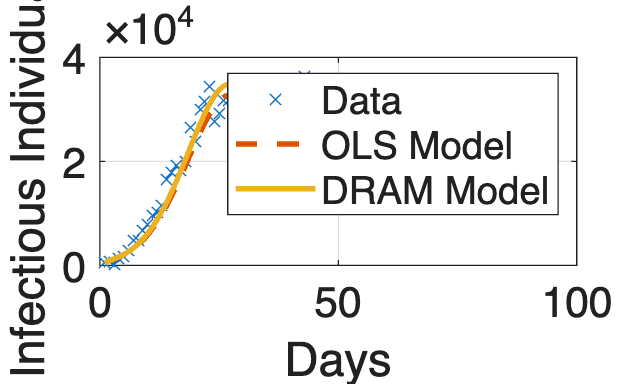


%% DRAM Posterior Mean Model
q_DRAM = mean(chain);
[~,Y_DRAM] = ode45(@(t,y) seir_rhs(t,y,q_DRAM,N_daily,t_daily), t_daily, Y0, odeopt);
I_DRAM = Y_DRAM(:,3);
D_DRAM = Y_DRAM(:,5);
F_DRAM = [D_DRAM(1); diff(D_DRAM)];

figure;
plot(t_daily, I_daily,'x'); hold on;
plot(t_daily, I_freq,'--','LineWidth',2);
plot(t_daily, I_DRAM,'-','LineWidth',2);
xlabel('Days'); ylabel('Infectious Individuals'); grid on;
legend('Data','OLS Model','DRAM Model'); set(gca,'FontSize',16);

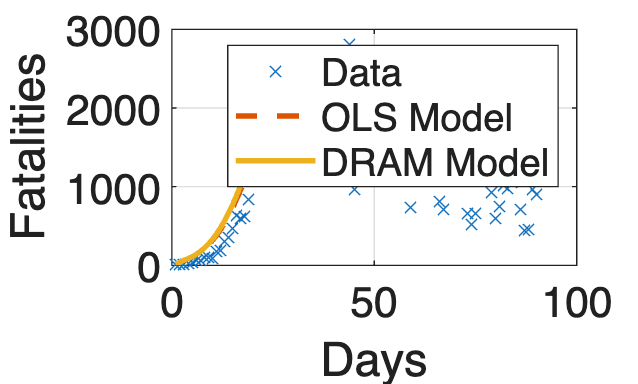


figure;
plot(t_daily, F_daily,'x'); hold on;
plot(t_daily, F_freq,'--','LineWidth',2);
plot(t_daily, F_DRAM,'-','LineWidth',2);
xlabel('Days'); ylabel('Fatalities'); grid on;
legend('Data','OLS Model','DRAM Model'); set(gca,'FontSize',16);

## Predicting Future Observations

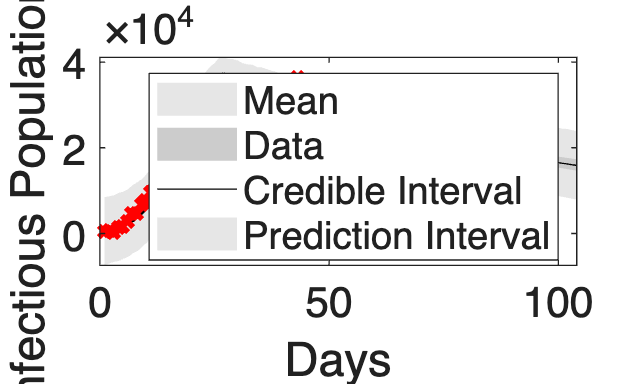

%% Bayesian Predictive Intervals
t_pred = linspace(min(t_daily), max(t_daily)+14, 100)';
nsample = 5000;
out = mcmcpred(results, chain, s2chain, t_pred, @(t,q) seir_Ipred(q,t,Y0,N_daily,t_daily,odeopt), nsample);

ltgray = [0.9 0.9 0.9];
medgray = [0.8 0.8 0.8];

figure; mcmcpredplot(out); hold on;
DRAMp_plot = patch(NaN,NaN,ltgray,'EdgeColor','none');
DRAMc_plot = patch(NaN,NaN,medgray,'EdgeColor','none');
mean_plot = plot(NaN,NaN,'-k','LineWidth',1);
data_plot = plot(t_daily,I_daily,'xr','LineWidth',2);
xlabel('Days'); ylabel('Infectious Population I(t)');
legend([mean_plot, data_plot, DRAMc_plot, DRAMp_plot], ...

    {'Posterior Predictive Mean','Data','Credible Interval','Prediction Interval'}); 
set(gca,'FontSize',14); box on;


## Local Functions

function [SS, I_model] = seir_ss(q, t_data, I_data, D_data, Y0, N, odeopt)
[~, Y] = ode45(@(t,y) seir_rhs(t,y,q,N,t_data), t_data, Y0, odeopt);
I_model = Y(:,3);
D_model = Y(:,5);
r_I = I_model - I_data;
r_D = D_model - D_data;
SS = (r_I'*r_I) + (r_D'*r_D);
end

function dy = seir_rhs(t, y, q, N, t_data)
N_t = interp1(t_data, N, t, 'linear','extrap');
S = y(1); E = y(2); I = y(3); R = y(4); D = y(5);
beta_1 = q(1); beta_2 = q(2); alpha = q(3); gamma = q(4); f = q(5); tchange = q(6);

% Determine the current beta based on time t
if t < tchange
    beta = beta_1 + (beta_2 - beta_1) * (t / tchange);
else
    beta = beta_2;
end

dS = -beta * S .* I ./ N_t; % Susceptible population change
dE = beta * S .* I ./ N_t - alpha * E; % Exposed population change
dI = alpha * E - (gamma + f) * I; % Infectious population change
dR = gamma * I; % Recovered population change
dD = f * I; % Deceased population change

dy = [dS; dE; dI; dR; dD];
end

function I_pred = seir_Ipred(q, t_pred, Y0, N_data, t_data, odeopt)
[~, Y] = ode45(@(t,y) seir_rhs(t,y,q,N_data,t_data), t_pred, Y0, odeopt);
I_pred = Y(:,3);
end